%Carga el modelo ya entrenado
cd('C:\Users\tsab\OneDrive\Documentos\tomato')
load('modeloTomate_resnet18_moderno.mat', 'netTransfer', 'labelsOrder');

%Exporta el modelo a ONNX
exportONNXNetwork(netTransfer,'tomatoNet.onnx','OpsetVersion',11);

%Exporta las etiquetas al mismo orden que tenía el modelo
writecell(labelsOrder, 'labels_tomato.txt');


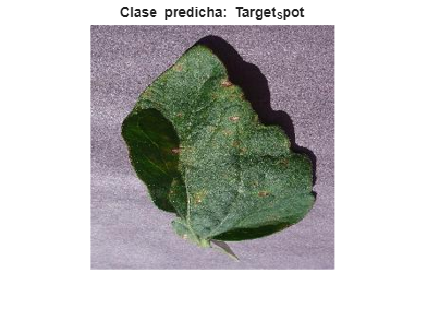


imagenPruebaPath = 'C:/Users/tsab/OneDrive/Documentos/tomato/targetspot1.jpg';

imagenPrueba = imread(imagenPruebaPath);

inputSize = netTransfer.Layers(1).InputSize(1:2);

imagenRedimensionada = imresize(imagenPrueba, inputSize);

[etiquetaPredicha, puntuaciones] = classify(netTransfer, imagenRedimensionada);

figure;
imshow(imagenRedimensionada);
title(['Clase predicha: ', char(etiquetaPredicha)]);


%Muestra las puntuaciones de confianza
disp('Puntuaciones de confianza para cada clase:');

Puntuaciones de confianza para cada clase:


disp('-------------------------------');

-------------------------------


disp('Clase          Puntuación');

Clase          Puntuación


disp('-------------------------------');

-------------------------------



%bucle para mostrar cada par de clase y puntuación
for i = 1:numel(labelsOrder)
    fprintf('%-15s %f\n', labelsOrder{i}, puntuaciones(i));
end

Bacterial_spot  0.001198
Early_blight    0.007012
Late_blight     0.000022
Leaf_Mold       0.000267
Septoria_leaf_spot 0.185681
Spider_mites Two-spotted_spider_mite 0.000029
Target_Spot     0.805356
Tomato_Yellow_Leaf_Curl_Virus 0.000000
Tomato_mosaic_virus 0.000331
healthy         0.000100
powdery_mildew  0.000004



disp('-------------------------------');

-------------------------------
